## Modelling Snake Robot Kinematics

Reference is taken from 

*F. Masaki, F. King, T. Kato, H. Tsukada, Y. L. Colson and N. Hata, "Technical validation of multi-section robotic bronchoscope with first person view control for transbronchial biopsies of peripheral lung," in IEEE Transactions on Biomedical Engineering, doi: 10.1109/TBME.2021.3077356.*

syms theta_1 theta_2 theta_3 phi_1 phi_2 phi_3 len_1 len_2 len_3

Notations as explained

Refer to Figure 1 in above mentioned reference paper for better understanding.

Rot_1_2 refers to rotation from coordinate system {S1} to coordinate system {S2}

t_1_2 refers to translation from coordinate system {S1} to coordinate system {S2}

T_1_2 gives the homogenous transformation matrix for transformation from coordinate system {S1} to coordinate system {S2}

We have 4 coordinate systems: S1 , S2 , S3 and Se ( for end effector)

Rot_1_2 = [cos(phi_1)^2*(cos(theta_1)-1)+1 sin(phi_1)*cos(phi_1)*(cos(theta_1)-1) cos(phi_1)*sin(theta_1);sin(phi_1)*cos(phi_1)*(cos(theta_1)-1) cos(phi_1)*cos(phi_1)*(1-cos(theta_1))+cos(theta_1) sin(phi_1)*sin(theta_1);-cos(phi_1)*sin(theta_1) sin(phi_1)*sin(theta_1) cos(theta_1)]

$$Rot\_1\_2 = \begin{array}{l} \left(\begin{array}{ccc} \left(\cos\left(\theta_{1}\right)-1\right)\,{\cos\left(\varphi_{1}\right)}^{2}+1 & \sigma_{1} & \cos\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{1} & \cos\left(\theta_{1}\right)-{\cos\left(\varphi_{1}\right)}^{2}\,\left(\cos\left(\theta_{1}\right)-1\right) & \sin\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right)\\ -\cos\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi_{1}\right)\,\sin\left(\varphi_{1}\right)\,\left(\cos\left(\theta_{1}\right)-1\right) \end{array}$$

Rot_2_3 = [cos(phi_2)^2*(cos(theta_2)-1)+1 sin(phi_2)*cos(phi_2)*(cos(theta_2)-1) cos(phi_2)*sin(theta_2);sin(phi_2)*cos(phi_2)*(cos(theta_2)-1) cos(phi_2)*cos(phi_2)*(1-cos(theta_2))+cos(theta_2) sin(phi_2)*sin(theta_2);-cos(phi_2)*sin(theta_2) sin(phi_2)*sin(theta_2) cos(theta_2)]

$$Rot\_2\_3 = \begin{array}{l} \left(\begin{array}{ccc} \left(\cos\left(\theta_{2}\right)-1\right)\,{\cos\left(\varphi_{2}\right)}^{2}+1 & \sigma_{1} & \cos\left(\varphi_{2}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{1} & \cos\left(\theta_{2}\right)-{\cos\left(\varphi_{2}\right)}^{2}\,\left(\cos\left(\theta_{2}\right)-1\right) & \sin\left(\varphi_{2}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\varphi_{2}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\varphi_{2}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi_{2}\right)\,\sin\left(\varphi_{2}\right)\,\left(\cos\left(\theta_{2}\right)-1\right) \end{array}$$

Rot_3_e = [cos(phi_3)^2*(cos(theta_3)-1)+1 sin(phi_3)*cos(phi_3)*(cos(theta_3)-1) cos(phi_3)*sin(theta_3);sin(phi_3)*cos(phi_3)*(cos(theta_3)-1) cos(phi_3)*cos(phi_3)*(1-cos(theta_3))+cos(theta_3) sin(phi_3)*sin(theta_3);-cos(phi_3)*sin(theta_3) sin(phi_3)*sin(theta_3) cos(theta_3)]

$$Rot\_3\_e = \begin{array}{l} \left(\begin{array}{ccc} \left(\cos\left(\theta_{3}\right)-1\right)\,{\cos\left(\varphi_{3}\right)}^{2}+1 & \sigma_{1} & \cos\left(\varphi_{3}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{1} & \cos\left(\theta_{3}\right)-{\cos\left(\varphi_{3}\right)}^{2}\,\left(\cos\left(\theta_{3}\right)-1\right) & \sin\left(\varphi_{3}\right)\,\sin\left(\theta_{3}\right)\\ -\cos\left(\varphi_{3}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\varphi_{3}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi_{3}\right)\,\sin\left(\varphi_{3}\right)\,\left(\cos\left(\theta_{3}\right)-1\right) \end{array}$$

t_1_2=len_1/theta_1 * [cos(phi_1)*(1-cos(theta_1));sin(phi_1)*(1-cos(theta_1)); sin(theta_1)]

$$t\_1\_2 = \left(\begin{array}{c} -\frac{{\mathrm{len}}_{1}\,\cos\left(\varphi_{1}\right)\,\left(\cos\left(\theta_{1}\right)-1\right)}{\theta_{1}}\\ -\frac{{\mathrm{len}}_{1}\,\sin\left(\varphi_{1}\right)\,\left(\cos\left(\theta_{1}\right)-1\right)}{\theta_{1}}\\ \frac{{\mathrm{len}}_{1}\,\sin\left(\theta_{1}\right)}{\theta_{1}} \end{array}\right)$$

t_2_3=len_2/theta_2 * [cos(phi_2)*(1-cos(theta_2));sin(phi_2)*(1-cos(theta_2)); sin(theta_2)]

$$t\_2\_3 = \left(\begin{array}{c} -\frac{{\mathrm{len}}_{2}\,\cos\left(\varphi_{2}\right)\,\left(\cos\left(\theta_{2}\right)-1\right)}{\theta_{2}}\\ -\frac{{\mathrm{len}}_{2}\,\sin\left(\varphi_{2}\right)\,\left(\cos\left(\theta_{2}\right)-1\right)}{\theta_{2}}\\ \frac{{\mathrm{len}}_{2}\,\sin\left(\theta_{2}\right)}{\theta_{2}} \end{array}\right)$$

t_3_e=len_3/theta_3 * [cos(phi_3)*(1-cos(theta_3));sin(phi_3)*(1-cos(theta_3)); sin(theta_3)]

$$t\_3\_e = \left(\begin{array}{c} -\frac{{\mathrm{len}}_{3}\,\cos\left(\varphi_{3}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)}{\theta_{3}}\\ -\frac{{\mathrm{len}}_{3}\,\sin\left(\varphi_{3}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)}{\theta_{3}}\\ \frac{{\mathrm{len}}_{3}\,\sin\left(\theta_{3}\right)}{\theta_{3}} \end{array}\right)$$


T_1_2 = [Rot_1_2 t_1_2; 0 0 0 1]

$$T\_1\_2 = \begin{array}{l} \left(\begin{array}{cccc} \left(\cos\left(\theta_{1}\right)-1\right)\,{\cos\left(\varphi_{1}\right)}^{2}+1 & \sigma_{1} & \sigma_{3} & -\frac{{\mathrm{len}}_{1}\,\cos\left(\varphi_{1}\right)\,\left(\cos\left(\theta_{1}\right)-1\right)}{\theta_{1}}\\ \sigma_{1} & \cos\left(\theta_{1}\right)-{\cos\left(\varphi_{1}\right)}^{2}\,\left(\cos\left(\theta_{1}\right)-1\right) & \sigma_{2} & -\frac{{\mathrm{len}}_{1}\,\sin\left(\varphi_{1}\right)\,\left(\cos\left(\theta_{1}\right)-1\right)}{\theta_{1}}\\ -\sigma_{3} & \sigma_{2} & \cos\left(\theta_{1}\right) & \frac{{\mathrm{len}}_{1}\,\sin\left(\theta_{1}\right)}{\theta_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi_{1}\right)\,\sin\left(\varphi_{1}\right)\,\left(\cos\left(\theta_{1}\right)-1\right)\\ \sigma_{2}=\sin\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\varphi_{1}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

T_2_3 = [Rot_2_3 t_2_3; 0 0 0 1]

$$T\_2\_3 = \begin{array}{l} \left(\begin{array}{cccc} \left(\cos\left(\theta_{2}\right)-1\right)\,{\cos\left(\varphi_{2}\right)}^{2}+1 & \sigma_{1} & \sigma_{3} & -\frac{{\mathrm{len}}_{2}\,\cos\left(\varphi_{2}\right)\,\left(\cos\left(\theta_{2}\right)-1\right)}{\theta_{2}}\\ \sigma_{1} & \cos\left(\theta_{2}\right)-{\cos\left(\varphi_{2}\right)}^{2}\,\left(\cos\left(\theta_{2}\right)-1\right) & \sigma_{2} & -\frac{{\mathrm{len}}_{2}\,\sin\left(\varphi_{2}\right)\,\left(\cos\left(\theta_{2}\right)-1\right)}{\theta_{2}}\\ -\sigma_{3} & \sigma_{2} & \cos\left(\theta_{2}\right) & \frac{{\mathrm{len}}_{2}\,\sin\left(\theta_{2}\right)}{\theta_{2}}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi_{2}\right)\,\sin\left(\varphi_{2}\right)\,\left(\cos\left(\theta_{2}\right)-1\right)\\ \sigma_{2}=\sin\left(\varphi_{2}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}=\cos\left(\varphi_{2}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

T_3_e = [Rot_3_e t_3_e; 0 0 0 1]

$$T\_3\_e = \begin{array}{l} \left(\begin{array}{cccc} \left(\cos\left(\theta_{3}\right)-1\right)\,{\cos\left(\varphi_{3}\right)}^{2}+1 & \sigma_{1} & \sigma_{3} & -\frac{{\mathrm{len}}_{3}\,\cos\left(\varphi_{3}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)}{\theta_{3}}\\ \sigma_{1} & \cos\left(\theta_{3}\right)-{\cos\left(\varphi_{3}\right)}^{2}\,\left(\cos\left(\theta_{3}\right)-1\right) & \sigma_{2} & -\frac{{\mathrm{len}}_{3}\,\sin\left(\varphi_{3}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)}{\theta_{3}}\\ -\sigma_{3} & \sigma_{2} & \cos\left(\theta_{3}\right) & \frac{{\mathrm{len}}_{3}\,\sin\left(\theta_{3}\right)}{\theta_{3}}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi_{3}\right)\,\sin\left(\varphi_{3}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)\\ \sigma_{2}=\sin\left(\varphi_{3}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{3}=\cos\left(\varphi_{3}\right)\,\sin\left(\theta_{3}\right) \end{array}$$


T_1_e = T_1_2*T_2_3*T_3_e

syms bend_theta bend_phi r_s

l_wire_a = r_s*bend_theta*cos(bend_phi)

$$l\_wire\_a = {\mathrm{bend}}_{\theta }\,r_{s}\,\cos\left({\mathrm{bend}}_{\varphi }\right)$$

l_wire_b = r_s*bend_theta*cos(bend_phi - 2*pi/3)

$$l\_wire\_b = {\mathrm{bend}}_{\theta }\,r_{s}\,\cos\left({\mathrm{bend}}_{\varphi }-\frac{2\,\pi }{3}\right)$$

l_wire_c = r_s*bend_theta*cos(bend_phi - 4*pi/3)

$$l\_wire\_c = {\mathrm{bend}}_{\theta }\,r_{s}\,\cos\left({\mathrm{bend}}_{\varphi }-\frac{4\,\pi }{3}\right)$$


len_calc = l_wire_a^2 + l_wire_b^2 + l_wire_c^2 - l_wire_a*l_wire_b - l_wire_b*l_wire_c - l_wire_c*l_wire_a

$$len\_calc = \begin{array}{l} {{\mathrm{bend}}_{\theta }}^{2}\,{r_{s}}^{2}\,{\cos\left({\mathrm{bend}}_{\varphi }\right)}^{2}-{{\mathrm{bend}}_{\theta }}^{2}\,{r_{s}}^{2}\,\cos\left({\mathrm{bend}}_{\varphi }\right)\,\sigma_{2}-{{\mathrm{bend}}_{\theta }}^{2}\,{r_{s}}^{2}\,\cos\left({\mathrm{bend}}_{\varphi }\right)\,\sigma_{1}+{{\mathrm{bend}}_{\theta }}^{2}\,{r_{s}}^{2}\,{\sigma_{2}}^{2}-{{\mathrm{bend}}_{\theta }}^{2}\,{r_{s}}^{2}\,\sigma_{2}\,\sigma_{1}+{{\mathrm{bend}}_{\theta }}^{2}\,{r_{s}}^{2}\,{\sigma_{1}}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\mathrm{bend}}_{\varphi }-\frac{4\,\pi }{3}\right)\\ \sigma_{2}=\cos\left({\mathrm{bend}}_{\varphi }-\frac{2\,\pi }{3}\right) \end{array}$$

Using the following for reference, the homogenous transformation which maps the lengths of wires to the end effector position is implemented

  *Jones, B.A, and I.D Walker. “Limiting-Case Analysis of Continuum Trunk Kinematics.” Proceedings 2007 IEEE International Conference on Robotics and Automation. IEEE, 2007. 1363–1368. Web.*

Note: Notations are used from the above mentioned paper

l_w_a = []


l_w_a =

     []



l_w_b = []


l_w_b =

     []



l_w_c = []


l_w_c =

     []



## Section 1 wire lengths

l_w_a(1)= 7

l_w_a = 7

l_w_b(1) = 5

l_w_b = 5

l_w_c(1)= 7

l_w_c = 7


g_1= l_w_a(1)^2 + l_w_b(1)^2 + l_w_c(1)^2 - l_w_a(1)*l_w_b(1) - l_w_b(1)*l_w_c(1) - l_w_a(1)*l_w_c(1)

g_1 = 4

## Section 2 wire lengths

l_w_a(2) = 7

l_w_a =      7     7


l_w_b(2) = 6

l_w_b =      5     6


l_w_c(2) = 5

l_w_c =      7     5



g_2= l_w_a(2)^2 + l_w_b(2)^2 + l_w_c(2)^2 - l_w_a(2)*l_w_b(2) - l_w_b(2)*l_w_c(2) - l_w_a(2)*l_w_c(2)

g_2 = 3

## Section 3 wire lengths

l_w_a(3) = 7

l_w_a =      7     7     7


l_w_b(3) = 8

l_w_b =      5     6     8


l_w_c(3) = 6

l_w_c =      7     5     6



g_3= l_w_a(3)^2 + l_w_b(3)^2 + l_w_c(3)^2 - l_w_a(3)*l_w_b(3) - l_w_b(3)*l_w_c(3) - l_w_a(3)*l_w_c(3)

g_3 = 3

d=2

d = 2

g =[g_1 g_2 g_3]

g =      4     3     3


%l = [l_1 l_2 l_3]
T_final=[1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]

T_final =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


for section = 1:3
    if g(section) == 0
        T_arm = [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1];
    else
        T_arm = [1-(3*(l_w_c(section)-l_w_b(section))^2*(1-cos(g(section)))/(4*g(section))) sqrt(3)*(l_w_c(section)-l_w_b(section))*(l_w_b(section)+l_w_c(section)-2*l_w_a(section))*(1-cos(g(section)))/(4*g(section)) -sqrt(3)*(l_w_c(section)-l_w_b(section))*sin(g(section))/(2*g(section)) -d*sqrt(3)*(l_w_c(section)-l_w_b(section))*(l_w_a(section)+l_w_b(section)+l_w_c(section))*(1-cos(g(section)))/(4*g(section));sqrt(3)*(l_w_c(section)-l_w_b(section))*(l_w_b(section)+l_w_c(section)-2*l_w_a(section))*(1-cos(g(section)))/(4*g(section)) cos(g(section))+((3*(l_w_c(section)-l_w_b(section))^2)-(3*l_w_b(section)^2+3*l_w_c(section)^2-6*l_w_b(section)*l_w_c(section))*cos(g(section)))/(4*g(section)) (l_w_b(section)+l_w_c(section)-2*l_w_a(section))*sin(g(section))/(2*sqrt(g(section))) -d*sqrt(3)*(l_w_a(section)+l_w_c(section)+l_w_b(section))*(l_w_b(section)+l_w_c(section)-2*l_w_a(section))*(1-cos(g(section)))/(4*g(section));sqrt(3)*(l_w_c(section)-l_w_b(section))*sin(g(section))/(2*g(section)) -(l_w_b(section)+l_w_c(section)-2*l_w_a(section))*sin(g(section))/(2*sqrt(g(section))) cos(g(section)) d*(l_w_a(section)+l_w_b(section)+l_w_c(section))*sin(g(section))/(2*sqrt(g(section))); 0 0 0 1];
    end
    T_final=T_final*T_arm
end

T_final =    -0.2402   -0.7160    0.3277  -13.6049
   -0.7160    0.5866    0.3784   13.6049
   -0.3277   -0.3784   -0.6536   -7.1896
         0         0         0    1.0000


T_final =    -0.7511    0.1857   -0.2467  -37.8209
    0.1302   -0.8597   -0.4755   24.9522
   -0.4641   -0.1759    0.6800  -23.2752
         0         0         0    1.0000


T_final =     0.7637    0.1857    0.1830  -56.3646
   -0.0902   -0.8597    0.4813   27.2808
    0.4041   -0.1759   -0.7110  -33.3094
         0         0         0    1.0000


fprintf("Final position of end effector : ")

Final position of end effector : 

x_end=T_final(1,4)

x_end = -56.3646

y_end=T_final(2,4)

y_end = 27.2808

z_end=T_final(3,4)

z_end = -33.3094

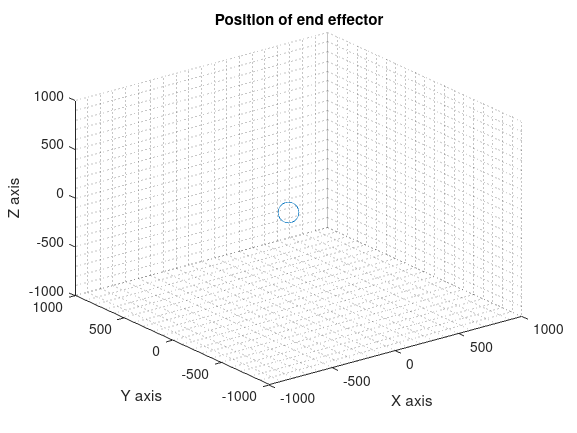

plot3(x_end,y_end,z_end,'o',"MarkerSize",15)
title("Position of end effector")
axis([-1000,1000,-1000,1000,-1000,1000])
xlabel("X axis")
ylabel("Y axis")
zlabel("Z axis")
grid("minor")